## Задание 2. Задача стабилизации с реальным дифференцирующим звеном

simTimeStart = 0;
simTimeEnd = 10;
step = 0.00001;
data.time=(simTimeStart:0.02:simTimeEnd)';
modelName = 'task2'; 

### Моделирование  движения - разомкнутая система

Эксперимент 1

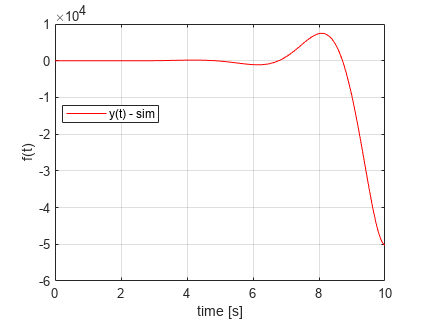

T = 6;
a0 = -3 ; a1 = -2 ; a2 =1; % coeff of the system
y0 = 3; y1 = 3; % initial state

k0 = -6; k1 = -4;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

figure;
plot(time, y_out, 'r');
hold on;
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'Location', 'Best');
save_file('output_task2_exp1')

Эксперимент 2

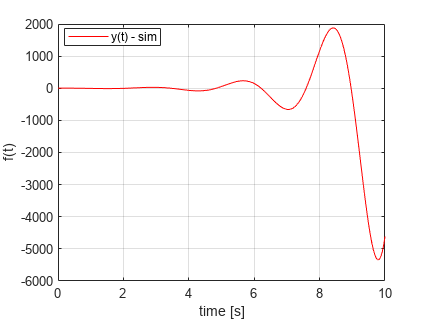

T = 1;
a0 = -3 ; a1 = -2 ; a2 =1; % coeff of the system
y0 = 3; y1 = 3; % initial state

k0 = -6; k1 = -4;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

figure;
plot(time, y_out, 'r');
hold on;
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'Location', 'Best');
save_file('output_task2_exp2')

Эксперимент 3

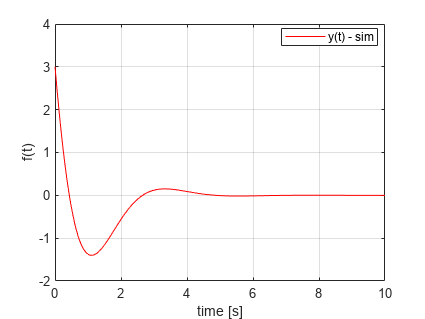

T = 0.001;
a0 = -3 ; a1 = -2 ; a2 =1; % coeff of the system
y0 = 3; y1 = 3; % initial state

k0 = -6; k1 = -4;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

figure;
plot(time, y_out, 'r');
hold on;
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'Location', 'Best');
save_file('output_task2_exp3')

Эксперимент 4

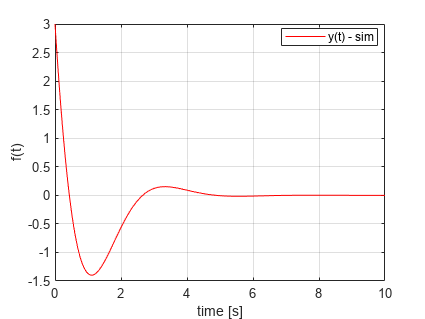

T = 0.00001;
a0 = -3 ; a1 = -2 ; a2 =1; % coeff of the system
y0 = 3; y1 = 3; % initial state

k0 = -6; k1 = -4;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 

figure;
plot(time, y_out, 'r');
hold on;
title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t) - sim', 'Location', 'Best');
save_file('output_task2_exp4')

Эксперимент 5,6,7,8

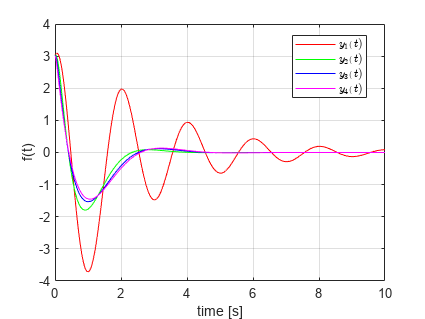

a0 = -3 ; a1 = -2 ; a2 =1; % coeff of the system
y0 = 3; y1 = 3; % initial state
k0 = -6; k1 = -4;

load_system(modelName);
T = 1/4; 
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
T = 1/12;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
T = 1/24;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
T = 1/48;
out4 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out1 = out1.simout.Data;
y_out2 = out2.simout.Data; 
y_out3 = out3.simout.Data; 
y_out4 = out4.simout.Data; 

figure;
plot(time, y_out1, 'r');
hold on;
plot(time, y_out2, 'g');
hold on;
plot(time, y_out3, 'b');
hold on;
plot(time, y_out4, 'magenta');
hold on;

title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t)$', '$y_2(t)$', '$y_3(t)$', '$y_4(t)$', 'Location', 'Best','Interpreter','latex');
save_file('output_task2_exp5')

Сравнение с первым заданием - блок против дифф звена 

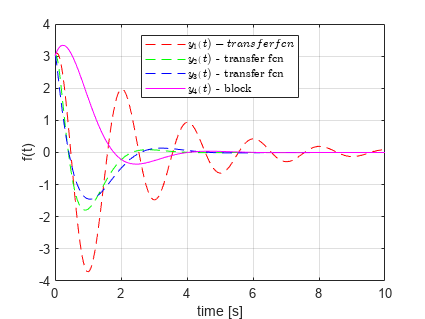

a0 = -3 ; a1 = -2 ; a2 =1; % coeff of the system
y0 = 3; y1 = 3; % initial state
k0 = -6; k1 = -4;

load_system(modelName);
T = 1/4; 
out1 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
T = 1/12;
out2 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
T = 1/48;
out3 = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

load_system('task12');
out4 = sim('task12', 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out1 = out1.simout.Data;
y_out2 = out2.simout.Data; 
y_out3 = out3.simout.Data; 
y_out4 = out4.simout.Data;

figure;
plot(time, y_out1, 'r--');
hold on;
plot(time, y_out2, 'g--');
hold on;
plot(time, y_out3, 'b--');
hold on;
plot(time, y_out4, 'magenta');
hold on;

title(' ');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('$y_1(t) - transfer fcn$', '$y_2(t)$ - transfer fcn', '$y_3(t)$ - transfer fcn', '$y_4(t)$ - block', 'Location', 'Best','Interpreter','latex');
save_file('output_task2_exp6')

**Функция, чтобы сохранить файл в папку**

function save_file(name)
    path = 'D:\Math\control_theory\linear_systems_labs\lab4\latex4\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end
